# Grad CFD HW #7 Problem 2

clear; close all; clc;
tic

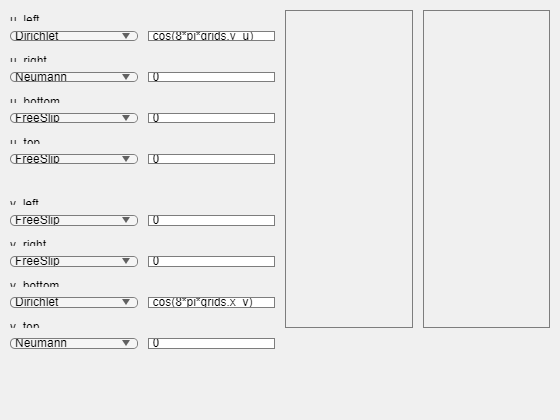

%% Begin UI
gui

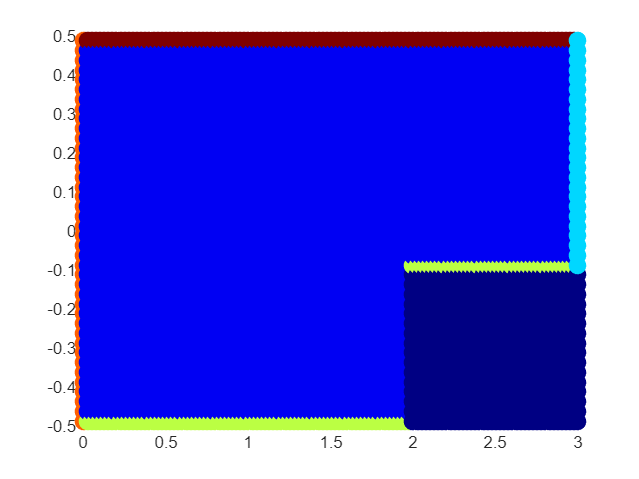

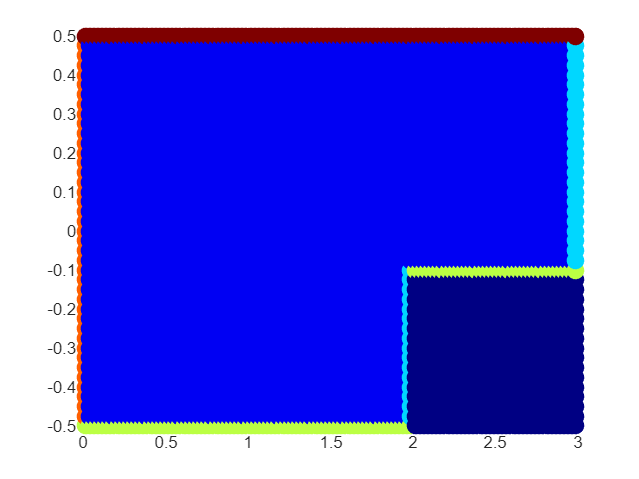

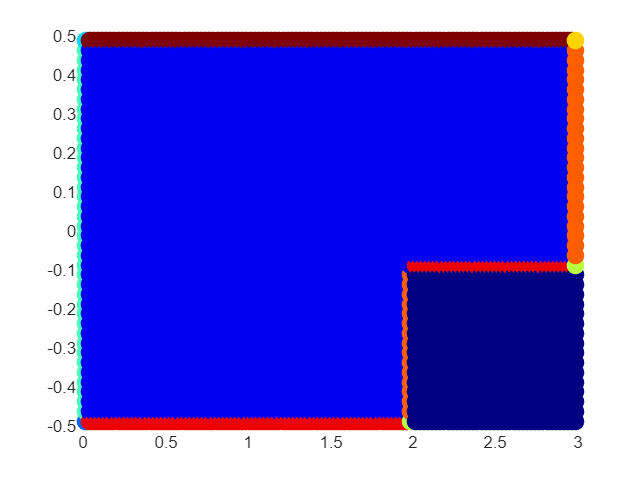


system_parameters                                     %% Set system and solver parameters
%% User clicks generate mesh button
mesh_generation                                       %% Create the domain by calling grid_generation.m and set_cell_type.m and creates cell-type visualizations

guess_initialization                                  %% Generate the initial guess for the system

%%%%%%%%%%%User inputs rest of BC's phi, NOT velocity Boundaries
BC.u_lef_type = "Dirichlet";        %x=0
BC.u_lef_value = cos(8*pi*grids.y_u);
BC.u_rig_type = "Neumann";         %x=1
BC.u_rig_value = 0;
BC.u_bot_type = "FreeSlip";
BC.u_bot_value = 0;
BC.u_top_type = "FreeSlip";
BC.u_top_value = 0;

BC.v_lef_type = "FreeSlip";
BC.v_lef_value = 0;
BC.v_rig_type = "FreeSlip";
BC.v_rig_value = 0;
BC.v_bot_type = "Dirichlet";        %y=0
BC.v_bot_value = cos(8*pi*grids.x_v);
BC.v_top_type = "Neumann";          %y=1
BC.v_top_value = 0;

%%Handle Constant Values
if isscalar(BC.u_lef_value)
    BC.u_lef_value = BC.u_lef_value*ones(N.y_p,1);
end
if isscalar(BC.u_rig_value)
    BC.u_rig_value = BC.u_rig_value*ones(N.y_p,1);
end
if isscalar(BC.u_bot_value)
    BC.u_bot_value = BC.u_bot_value*ones(N.x_p,1);
end
if isscalar(BC.u_top_value)
    BC.u_top_value = BC.u_top_value*ones(N.x_p,1);
end
if isscalar(BC.v_lef_value)
    BC.v_lef_value = BC.v_lef_value*ones(N.y_p,1);
end
if isscalar(BC.v_rig_value)
    BC.v_rig_value = BC.v_rig_value*ones(N.y_p,1);
end
if isscalar(BC.v_bot_value)
    BC.v_bot_value = BC.v_bot_value*ones(N.x_p,1);
end
if isscalar(BC.v_top_value)
    BC.v_top_value = BC.v_top_value*ones(N.x_p,1);
end


for n = 1%:Nt-1                                       %%%%%%%%%%%%%% TIME MARCHING
    time_step_initialization                          %% Set the variables to begin a new time step
    simple_algorithm                                  %% Begin recursive calculation of u^n+1 and v^n+1 uasing A_u, A_v, and A_p
    % heat_transfer_step                                %% Perform a heat transfer step
    plot_store_results                                %% Plot results and store the u^n+1, v^n+1, and p^n+1 fields
end

toc

Elapsed time is 23.675535 seconds.
